Punto 1.a)

T=0.2;
time = 0:T:10;
y0=1;
yDis(1)=y0;
for k=[1:length(time)-1]
    yDis(k+1)=yDis(k)*(1-2*time(k+1));
end
yDis

time =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


Punto 2.a)

clf
syms y(t)
T=1;
time=0:T:10;
y0=1;
yDis=t;
yCont=yDis;
yDis(1)=y0;
for k=[2:length(time)]
    yDis((k))=0.6*yDis(k-1);
end
yDis

$$yDis = \left(\begin{array}{ccccccccccc} 1 & \frac{3}{5} & \frac{9}{25} & \frac{27}{125} & \frac{81}{625} & \frac{243}{3125} & \frac{729}{15625} & \frac{2187}{78125} & \frac{6561}{390625} & \frac{19683}{1953125} & \frac{59049}{9765625} \end{array}\right)$$

clf
figure(1)
grid on
stem(time,vpa(yDis))
hold on
y= 0.6^(t);
fplot(y,[0 10])
xlabel('t')
ylabel('y')

punto 2.b) 

clf
syms y(t)

time=0:10;
yDis=t;
yCont=yDis;
yDis(1)=0;
yDis(2)=1;

for k=[1:length(time)-2]
    yDis((k+2))=4*yDis(k+1)-3*yDis(k);
end

figure(1)

stem(time,vpa(yDis))
grid on
hold on
y= (3^t)*(1/2)-1/2;
fplot(y,[0 10])
xlabel('t')
ylabel('y')

punto 2.c)

%%
clf
syms y(t)

time=0:10;
yDis=t;
yCont=yDis;
yDis(1)=0;
yDis(2)=-1;

for k=[1:length(time)-2]
    yDis((k+2))=-0.1*yDis(k+1)+0.02*yDis(k);
end

y= (-10/3)*(1/10)^t + (10/3)*(-1/5)^t;
ysol=subs(y,t,time)

$$ysol = \left(\begin{array}{ccccccccccc} 0 & -1 & \frac{1}{10} & -\frac{3}{100} & \frac{1}{200} & -\frac{11}{10000} & \frac{21}{100000} & -\frac{43}{1000000} & \frac{17}{2000000} & -\frac{171}{100000000} & \frac{341}{1000000000} \end{array}\right)$$


figure(1)

stem(time,vpa(yDis))
grid on
hold on
plot(time,ysol)


xlabel('t')
ylabel('y')

punto 2.d)

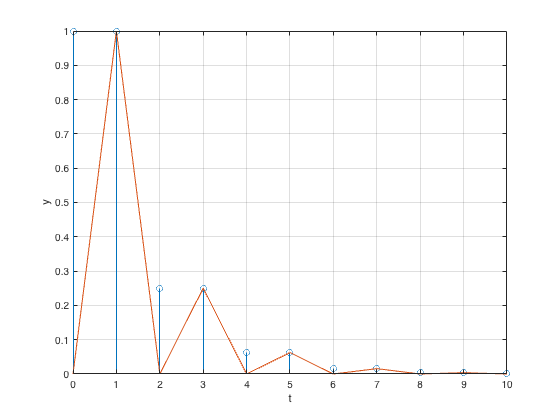

clf
syms y(t)

time=0:10;
yDis=t;
yCont=yDis;
yDis(1)=1;
yDis(2)=1;
for k=[1:length(time)-2]
    yDis((k+2))=0.25*yDis(k);
end

y= (1/2)^t - (-1/2)^t;
ysol=subs(y,t,time);
figure(1)

stem(time,vpa(yDis))
grid on
hold on
plot(time,ysol)


xlabel('t')
ylabel('y')

punto 2.e)

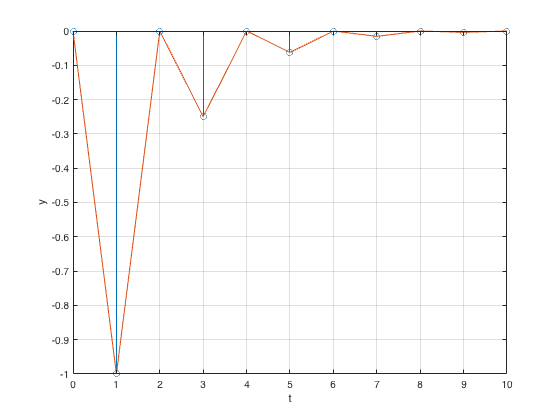

clf
syms y(t)

time=0:10;
yDis=t;
yCont=yDis;
yDis(1)=0;
yDis(2)=-1;
for k=[1:length(time)-2]
    yDis((k+2))=0.25*yDis(k);
end

y= -(1/2)^t + (-1/2)^t;
ysol=subs(y,t,time);
figure(1)

stem(time,vpa(yDis))
grid on
hold on
plot(time,ysol)


xlabel('t')
ylabel('y')

punto 2.e)

clf
syms y(t)

time=0:10;
yDis=t;
yCont=yDis;
yDis(1)=0;
yDis(2)=-1;
for k=[1:length(time)-2]
    yDis((k+2))=0.25*yDis(k);
end

y= -(1/2)^t + (-1/2)^t;
ysol=subs(y,t,time);
figure(1)

stem(time,vpa(yDis))
grid on
hold on
plot(time,ysol)


xlabel('t')
ylabel('y')




Función de transferencia

clf
syms y(t)
syms u(t)
syms s
syms G(s)
ode = diff(diff(y,t),t) + 3*diff(y,t) + 4*y == diff(u,t)+3*u

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+4\,y\left(t\right)=\frac{\partial }{\partial t}u\left(t\right)+3\,u\left(t\right)$$


odelaplace = laplace(ode)

$$odelaplace = 3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-3\,y\left(0\right)-s\,y\left(0\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+4\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=s\,\mathrm{laplace}\left(u\left(t\right),t,s\right)-u\left(0\right)+3\,\mathrm{laplace}\left(u\left(t\right),t,s\right)$$



odes = 3*s*laplace(y(t), t, s) + s^2*laplace(y(t), t, s) + 4*laplace(y(t), t, s) == s*laplace(u(t), t, s) + 3*laplace(u(t), t, s)

$$odes = 3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+4\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=s\,\mathrm{laplace}\left(u\left(t\right),t,s\right)+3\,\mathrm{laplace}\left(u\left(t\right),t,s\right)$$


simplify(odes)

$$ans = \left(s+3\right)\,\mathrm{laplace}\left(u\left(t\right),t,s\right)=\left(s^{2}+3\,s+4\right)\,\mathrm{laplace}\left(y\left(t\right),t,s\right)$$

G = (s + 3)/(s^2 + 3*s + 4)

$$G = \frac{s+3}{s^{2}+3\,s+4}$$


ilaplace(G)

$$ans = {\mathrm{e}}^{-\frac{3\,t}{2}}\,\left(\cos\left(\frac{\sqrt{7}\,t}{2}\right)+\frac{3\,\sqrt{7}\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)}{7}\right)$$

1)a

clf
syms y(t)
syms u(t)
syms s
syms G(s)

ode = diff(diff(y,t),t) + 3*diff(y,t) + 2*y == u;
odelaplace = laplace(ode)

$$odelaplace = 3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-3\,y\left(0\right)-s\,y\left(0\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=\mathrm{laplace}\left(u\left(t\right),t,s\right)$$

odes = 3*s*laplace(y(t), t, s) + s^2*laplace(y(t), t, s)+2*laplace(y(t), t, s) == laplace(u(t), t, s);

odeinv = simplify(odes)

$$odeinv = \mathrm{laplace}\left(u\left(t\right),t,s\right)=\left(s^{2}+3\,s+2\right)\,\mathrm{laplace}\left(y\left(t\right),t,s\right)$$


G = 1/(s^2 + 3*s + 2)

$$G = \frac{1}{s^{2}+3\,s+2}$$


ilaplace(odeinv)

$$ans = u\left(t\right)=2\,y\left(t\right)+\delta (t)\,\left({\left(\frac{\partial }{\partial s}y\left(s\right)\right)|}_{s=0}\right)+3\,y\left(0\right)\,\delta (t)+y\left(0\right)\,\delta^{\prime }(t)+3\,\frac{\partial }{\partial t}y\left(t\right)+\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$

1.f)

clf

syms y(t)
syms u(t)
syms s
syms G(s)
syms T
syms tao



ode = T*diff(y,t) + y == u(t-tao);
odelaplace = laplace(ode)

$$odelaplace = \mathrm{laplace}\left(y\left(t\right),t,s\right)-T\,\left(y\left(0\right)-s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)\right)=\mathrm{laplace}\left(u\left(t-\mathrm{tao}\right),t,s\right)$$

odes = T*s*laplace(y(t), t, s) + laplace(y(t), t, s) == laplace(u(t - tao), t, s)

$$odes = \mathrm{laplace}\left(y\left(t\right),t,s\right)+T\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=\mathrm{laplace}\left(u\left(t-\mathrm{tao}\right),t,s\right)$$


odeinv = simplify(odes)

$$odeinv = \left(T\,s+1\right)\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=\mathrm{laplace}\left(u\left(t-\mathrm{tao}\right),t,s\right)$$


%G(s) = 



clf


syms y(k) z 
syms u(k) z %se declara la función simbólica y(k) y la variable simbólica z
assume(k>=0 & in(k,'integer')) % se establece que k es entero mayor o igual a 0
f = y(k+1)+0.5*y(k)==u(k) 

$$f = y\left(k+1\right)+\frac{y\left(k\right)}{2}=u\left(k\right)$$


fZT = ztrans(f,k,z)

$$fZT = z\,\mathrm{ztrans}\left(y\left(k\right),k,z\right)-z\,y\left(0\right)+\frac{\mathrm{ztrans}\left(y\left(k\right),k,z\right)}{2}=\mathrm{ztrans}\left(u\left(k\right),k,z\right)$$

fZT = subs(fZT,[y(0)],[0])

$$fZT = z\,\mathrm{ztrans}\left(y\left(k\right),k,z\right)+\frac{\mathrm{ztrans}\left(y\left(k\right),k,z\right)}{2}=\mathrm{ztrans}\left(u\left(k\right),k,z\right)$$

syms Yz
syms Uz%variable para resolver la ecuación
transformada = fZT

$$transformada = z\,\mathrm{ztrans}\left(y\left(k\right),k,z\right)+\frac{\mathrm{ztrans}\left(y\left(k\right),k,z\right)}{2}=\mathrm{ztrans}\left(u\left(k\right),k,z\right)$$

fZT = subs(fZT,ztrans(y(k),k,z),Yz) 

$$fZT = \frac{\mathrm{Yz}}{2}+\mathrm{Yz}\,z=\mathrm{ztrans}\left(u\left(k\right),k,z\right)$$

fZT = subs(fZT,ztrans(u(k),k,z),Uz) 

$$fZT = \frac{\mathrm{Yz}}{2}+\mathrm{Yz}\,z=\mathrm{Uz}$$

fZT = simplify(fZT)

$$fZT = 2\,\mathrm{Uz}=\mathrm{Yz}\,\left(2\,z+1\right)$$


Uz = simplify(solve(fZT,Uz))

$$Uz = \frac{\mathrm{Yz}\,\left(2\,z+1\right)}{2}$$

Yz = simplify(solve(fZT,Yz))

$$Yz = \frac{2\,\mathrm{Uz}}{2\,z+1}$$


Gz = Yz/Uz

$$Gz = \frac{4\,\mathrm{Uz}}{\mathrm{Yz}\,{\left(2\,z+1\right)}^{2}}$$



iztrans(transformada,z,k) 

$$ans = y\left(k+1\right)+\frac{y\left(k\right)}{2}+y\left(0\right)\,\mathrm{iztrans}\left(z,z,k\right)=u\left(k\right)$$

Punto 2

2.a)

clf
syms G(s)
syms u(t) s
syms Y(s)
G = 1/(s+1)

$$G = \frac{1}{s+1}$$

u = 1;
U = laplace(u,t,s)

$$U = \frac{1}{s}$$

Y = G * U

$$Y = \frac{1}{s\,\left(s+1\right)}$$

Y = partfrac(Y)

$$Y = \frac{1}{s}-\frac{1}{s+1}$$

y = ilaplace(Y)

$$y = 1-{\mathrm{e}}^{-t}$$

sys = tf(1,[1 1]);
time = 0:0.5:50; 
us = ones(size(time));

ysol=subs(y,t,time);

plot(time,ysol)

lsim(sys,us,time)

2.b)

clf
syms G(s)
syms u(t) s
syms Y(s)
G = (exp(-2*s))/(s+1)

$$G = \frac{{\mathrm{e}}^{-2\,s}}{s+1}$$

u = 1;
U = laplace(u,t,s)

$$U = \frac{1}{s}$$

Y = G * U

$$Y = \frac{{\mathrm{e}}^{-2\,s}}{s\,\left(s+1\right)}$$

Y = partfrac(Y)

$$Y = \frac{{\mathrm{e}}^{-2\,s}}{s}-\frac{{\mathrm{e}}^{-2\,s}}{s+1}$$

y = ilaplace(Y)

$$y = \mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-2\right)\,{\mathrm{e}}^{2-t}$$


sys = tf(1,[1 1], 'InputDelay',2);
time = 0:0.5:50; 
us = ones(size(time));

ysol=subs(y,t,time);

plot(time,ysol)

lsim(sys,us,time)

clf
syms G(s)
syms u(t) s
syms Y(s)
G = 1/(s+1)

$$G = \frac{1}{s+1}$$

u = sin(t);
U = laplace(u,t,s)

$$U = \frac{1}{s^{2}+1}$$

Y = G * U

$$Y = \frac{1}{\left(s^{2}+1\right)\,\left(s+1\right)}$$


Y = partfrac(Y)

$$Y = \frac{1}{2\,\left(s+1\right)}-\frac{\frac{s}{2}-\frac{1}{2}}{s^{2}+1}$$

y = ilaplace(Y)

$$y = \frac{{\mathrm{e}}^{-t}}{2}-\frac{\cos\left(t\right)}{2}+\frac{\sin\left(t\right)}{2}$$


sys = tf(1,[1 1]);
time = 0:0.5:50; 


us =sin(time);

ysol=subs(y,t,time);

plot(time,ysol)

lsim(sys,us,time)

clf

syms G(z)
syms U(z)
syms Y(z)
syms n
G = (2*(z-0.2)*(z+0.3))/(z^2*(z-0.22)*(z+0.8)*(z+0.5)^2);
%u = deltakroneker
U = 1;
Y = G*U;
Y=partfrac(Y);
y = iztrans(Y)

$$y = \frac{30\,\delta_{n-2,0}}{11}-\frac{1565\,\delta_{n-1,0}}{242}-\frac{11020\,{\left(-\frac{1}{2}\right)}^{n}}{243}+\frac{78125\,{\left(-\frac{4}{5}\right)}^{n}}{3672}+\frac{20312500\,{\left(\frac{11}{50}\right)}^{n}}{5498361}-\frac{3845\,\delta_{n,0}}{10648}-\frac{560\,{\left(-\frac{1}{2}\right)}^{n}\,\left(n-1\right)}{27}$$

time = 0:1:100;  % 201 points

G = zpk([0.2 -0.3],[0 0 0.22 -0.8 -0.5 -0.5],2,1)

G =
 
        2 (z-0.2) (z+0.3)
  ------------------------------
  z^2 (z-0.22) (z+0.5)^2 (z+0.8)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



plot(time,subs(y,n,time))


u = ones(size(time));
lsim(G,u,time)

2.z)

clf
syms G(s)
syms u(t) s
syms Y(s)
G = (1/((s+1)*(s+2)))*[1 0; -2 s+3; s+4 -s-4];
u = [1;-1];
U = laplace(u,t,s);
Y = G*U

$$Y = \left(\begin{array}{c} \frac{1}{s\,\left(s+1\right)\,\left(s+2\right)}\\ -\frac{2}{s\,\left(s+1\right)\,\left(s+2\right)}-\frac{s+3}{s\,\left(s+1\right)\,\left(s+2\right)}\\ \frac{2\,\left(s+4\right)}{s\,\left(s+1\right)\,\left(s+2\right)} \end{array}\right)$$

Y=partfrac(Y)

$$Y = \left(\begin{array}{c} \frac{1}{2\,\left(s+2\right)}-\frac{1}{s+1}+\frac{1}{2\,s}\\ \frac{4}{s+1}-\frac{3}{2\,\left(s+2\right)}-\frac{5}{2\,s}\\ \frac{2}{s+2}-\frac{6}{s+1}+\frac{4}{s} \end{array}\right)$$

y = ilaplace(Y)

$$y = \left(\begin{array}{c} \frac{{\mathrm{e}}^{-2\,t}}{2}-{\mathrm{e}}^{-t}+\frac{1}{2}\\ 4\,{\mathrm{e}}^{-t}-\frac{3\,{\mathrm{e}}^{-2\,t}}{2}-\frac{5}{2}\\ 2\,{\mathrm{e}}^{-2\,t}-6\,{\mathrm{e}}^{-t}+4 \end{array}\right)$$

5. Secuencia de ponderación

5.a)

%funcion de ponderacion
%respuesta al impulso
syms G(z) k;
syms n;
syms h(k);
G = (0.2*z)/(z+0.1);
g = iztrans(G)

$$g = \frac{{\left(-\frac{1}{10}\right)}^{n}}{5}$$

time = 0:1:5;
f = subs(g,n,time);
plot(f);


%funcion de ponderacion respuesta a u=1
u=1;
k=5;
for i = 0:k
    symsum(g*u, 0, i)
end

$$ans = \frac{1}{5}$$

$$ans = \frac{9}{50}$$

$$ans = \frac{91}{500}$$

$$ans = \frac{909}{5000}$$

$$ans = \frac{9091}{50000}$$

$$ans = \frac{90909}{500000}$$

syms y(t)

f = diff(diff(y))+2*diff(y)+2*y == 0

$$f(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+2\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=0$$

Dy = diff(f)

$$Dy(t) = \frac{\partial^{3}}{\partial t^{3}}y\left(t\right)+2\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+2\,\frac{\partial }{\partial t}y\left(t\right)=0$$

dsolve(f)

$$ans = C_{1}\,{\mathrm{e}}^{-t}\,\cos\left(t\right)-C_{2}\,{\mathrm{e}}^{-t}\,\sin\left(t\right)$$

Reducción de orden

2.a)

clf
clear
syms G(s)
syms Gbar(s)
syms k 

G = 2*(s+4)/((s+1)*(s+3)*(s+4.05))

$$G = \frac{2\,s+8}{\left(s+1\right)\,\left(s+3\right)\,\left(s+\frac{81}{20}\right)}$$

Gbar = 2/((s+1)*(s+3)) * k;

f = subs(Gbar,s,0) == subs(G,s,0);

kvalue = solve(f,k);

Gbar = subs(Gbar,k,kvalue)

$$Gbar = \frac{160}{81\,\left(s+1\right)\,\left(s+3\right)}$$


g= zpk([-4],[-1,-3,-4.05],2)

g =
 
        2 (s+4)
  --------------------
  (s+1) (s+3) (s+4.05)
 
Continuous-time zero/pole/gain model.




gbar = zpk([],[-1,-3],160/81)

gbar =
 
    1.9753
  -----------
  (s+1) (s+3)
 
Continuous-time zero/pole/gain model.



step(g,gbar)

balred(g)



[aproxg,info] = balred(g,1);

aproxg

aproxg =
 
  -0.10572 (s-5.33)
  -----------------
     (s+0.8557)
 
Continuous-time zero/pole/gain model.




step(g,aproxg)

2.b)

clf
clear
syms G(s)
syms Gbar(s)
syms k 

G = 1.5*(s+1.1)*(s+4.8)/((s+1)*(s+3)*(s+5));
Gbar = 1.5/(s+3) * k;

f = subs(Gbar,s,0) == subs(G,s,0);

kvalue = solve(f,k);

Gbar = subs(Gbar,k,kvalue)

$$Gbar = \frac{198}{125\,\left(s+3\right)}$$


g = zpk([-1.1 -4.8],[-1 -3 -5],1.5)

g =
 
  1.5 (s+1.1) (s+4.8)
  -------------------
   (s+1) (s+3) (s+5)
 
Continuous-time zero/pole/gain model.



a = 1.5 * kvalue;
gbar = zpk([-1.1],[-1 -3],a)

Error using zpk (line 316)
The value of the "K" property must be a numeric array.


step(g,gbar)


Espacio de estado

3.a)

clf
clear
syms X(t)
syms C1
syms C2

A = sym([2 3;2 1]);

[vec val] = eig(A);



X1 = vec(:,1)*exp(val(1,1)*t);
X2 = vec(:,2)*exp(val(2,2)*t);

X = C1 * X1 + C2 * X2;



X0 = subs(X,t,0) == [1;1];
[c1 c2] = solve(X0,C1,C2);

X = subs(X,C1,c1);
X = subs(X,C2,c2)

$$X = \left(\begin{array}{c} \frac{6\,{\mathrm{e}}^{4\,t}}{5}-\frac{{\mathrm{e}}^{-t}}{5}\\ \frac{{\mathrm{e}}^{-t}}{5}+\frac{4\,{\mathrm{e}}^{4\,t}}{5} \end{array}\right)$$

2.b)

clf
clear
syms X(t)
syms C1
syms C2

A = sym([2 3;2 1]);
B = [1;-1];

[vec val] = eig(A);



X1 = vec(:,1)*exp(val(1,1)*t);
X2 = vec(:,2)*exp(val(2,2)*t);

X = C1 * X1 + C2 * X2;

phi = [X1 X2]

$$phi = \left(\begin{array}{cc} -{\mathrm{e}}^{-t} & \frac{3\,{\mathrm{e}}^{4\,t}}{2}\\ {\mathrm{e}}^{-t} & {\mathrm{e}}^{4\,t} \end{array}\right)$$

u=1;
F = B*u;


phiinv = inv(phi)

$$phiinv = \left(\begin{array}{cc} -\frac{2\,{\mathrm{e}}^{t}}{5} & \frac{3\,{\mathrm{e}}^{t}}{5}\\ \frac{2\,{\mathrm{e}}^{-4\,t}}{5} & \frac{2\,{\mathrm{e}}^{-4\,t}}{5} \end{array}\right)$$

int(phiinv*F)

$$ans = \left(\begin{array}{c} -{\mathrm{e}}^{t}\\ 0 \end{array}\right)$$

Xp = phi* int(phiinv*F,t)

$$Xp = \left(\begin{array}{c} 1\\ -1 \end{array}\right)$$

X = C1*X1 + C2*X2 + Xp

$$X = \left(\begin{array}{c} \frac{3\,C_{2}\,{\mathrm{e}}^{4\,t}}{2}-C_{1}\,{\mathrm{e}}^{-t}+1\\ C_{1}\,{\mathrm{e}}^{-t}+C_{2}\,{\mathrm{e}}^{4\,t}-1 \end{array}\right)$$

X0 = subs(X,t,0) == [0;1];
[c1 c2] = solve(X0,C1,C2);

X = subs(X,C1,c1);
X = subs(X,C2,c2)

$$X = \left(\begin{array}{c} \frac{3\,{\mathrm{e}}^{4\,t}}{5}-\frac{8\,{\mathrm{e}}^{-t}}{5}+1\\ \frac{8\,{\mathrm{e}}^{-t}}{5}+\frac{2\,{\mathrm{e}}^{4\,t}}{5}-1 \end{array}\right)$$


time = 0:1:50;

Xsol = subs(X,t,time);
plot(Xsol(:,1))

clf
clear
syms X(t)
syms C1
syms C2
syms s
syms tao

A = sym([2 3;2 1]);

X0 = [1;1];



[vec val] = eig(A);

phi = ilaplace(inv(s*eye(2)-A))

$$phi = \left(\begin{array}{cc} \frac{2\,{\mathrm{e}}^{-t}}{5}+\frac{3\,{\mathrm{e}}^{4\,t}}{5} & \frac{3\,{\mathrm{e}}^{4\,t}}{5}-\frac{3\,{\mathrm{e}}^{-t}}{5}\\ \frac{2\,{\mathrm{e}}^{4\,t}}{5}-\frac{2\,{\mathrm{e}}^{-t}}{5} & \frac{3\,{\mathrm{e}}^{-t}}{5}+\frac{2\,{\mathrm{e}}^{4\,t}}{5} \end{array}\right)$$


X = phi*X0 

$$X = \left(\begin{array}{c} \frac{6\,{\mathrm{e}}^{4\,t}}{5}-\frac{{\mathrm{e}}^{-t}}{5}\\ \frac{{\mathrm{e}}^{-t}}{5}+\frac{4\,{\mathrm{e}}^{4\,t}}{5} \end{array}\right)$$

clf
clear
syms X(t)
syms C1
syms C2
syms C3
syms s
syms tao

A = sym([1 -2 2;-2 1 -2; 2 -2 1]);

X0 = [1;-1;0];



[vec val] = eig(A)

$$vec = \left(\begin{array}{ccc} 1 & 1 & -1\\ -1 & 1 & 0\\ 1 & 0 & 1 \end{array}\right)$$

$$val = \left(\begin{array}{ccc} 5 & 0 & 0\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$


phi = ilaplace(inv(s*eye(3)-A))

$$phi = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & \sigma_{1} & \frac{{\mathrm{e}}^{5\,t}}{3}-\frac{{\mathrm{e}}^{-t}}{3}\\ \sigma_{1} & \sigma_{2} & \sigma_{1}\\ \frac{{\mathrm{e}}^{5\,t}}{3}-\frac{{\mathrm{e}}^{-t}}{3} & \sigma_{1} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-t}}{3}-\frac{{\mathrm{e}}^{5\,t}}{3}\\ \sigma_{2}=\frac{2\,{\mathrm{e}}^{-t}}{3}+\frac{{\mathrm{e}}^{5\,t}}{3} \end{array}$$


X = phi*X0

$$X = \left(\begin{array}{c} \frac{{\mathrm{e}}^{-t}}{3}+\frac{2\,{\mathrm{e}}^{5\,t}}{3}\\ -\frac{{\mathrm{e}}^{-t}}{3}-\frac{2\,{\mathrm{e}}^{5\,t}}{3}\\ \frac{2\,{\mathrm{e}}^{5\,t}}{3}-\frac{2\,{\mathrm{e}}^{-t}}{3} \end{array}\right)$$


X1 = vec(:,1)*exp(val(1,1)*t);
X2 = vec(:,2)*exp(val(2,2)*t);
X3 = vec(:,3)*exp(val(3,3)*t);

X = C1 * X1 + C2 * X2  + C3*X3;
X0 = subs(X,t,0) == X0;
[c1 c2 c3] = solve(X0,C1,C2,C3);

X = subs(X,C1,c1);
X = subs(X,C2,c2);
X = subs(X,C3,c3)

$$X = \left(\begin{array}{c} \frac{{\mathrm{e}}^{-t}}{3}+\frac{2\,{\mathrm{e}}^{5\,t}}{3}\\ -\frac{{\mathrm{e}}^{-t}}{3}-\frac{2\,{\mathrm{e}}^{5\,t}}{3}\\ \frac{2\,{\mathrm{e}}^{5\,t}}{3}-\frac{2\,{\mathrm{e}}^{-t}}{3} \end{array}\right)$$

clf
clear
syms X(t)
syms C1
syms C2
syms C3
syms s
syms tao
syms P
syms X1 X2 X3

A = sym([2 1 6;0 2 5; 0 0 2]);

X0 = [0;-1;1];

phi = ilaplace(inv(s*eye(3)-A))

$$phi = \left(\begin{array}{ccc} {\mathrm{e}}^{2\,t} & t\,{\mathrm{e}}^{2\,t} & 6\,t\,{\mathrm{e}}^{2\,t}+\frac{5\,t^{2}\,{\mathrm{e}}^{2\,t}}{2}\\ 0 & {\mathrm{e}}^{2\,t} & 5\,t\,{\mathrm{e}}^{2\,t}\\ 0 & 0 & {\mathrm{e}}^{2\,t} \end{array}\right)$$

X = phi*X0

$$X = \left(\begin{array}{c} 5\,t\,{\mathrm{e}}^{2\,t}+\frac{5\,t^{2}\,{\mathrm{e}}^{2\,t}}{2}\\ 5\,t\,{\mathrm{e}}^{2\,t}-{\mathrm{e}}^{2\,t}\\ {\mathrm{e}}^{2\,t} \end{array}\right)$$


[vec val] = eig(A)

$$vec = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

$$val = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & 2 & 0\\ 0 & 0 & 2 \end{array}\right)$$


f = (A-val(1,1)*eye(3))*[X1; X2; X3]== vec

$$f = \left(\begin{array}{c} X_{2}+6\,X_{3}=1\\ 5\,X_{3}=0\\ 0=0 \end{array}\right)$$

[x1,x2,x3] = solve(f,X1,X2,X3)

$$x1 = 0$$

$$x2 = 1$$

$$x3 = 0$$

P = [x1;x2;x3];
syms Y1 Y2 Y3




f1 = (A-val(1,1)*eye(3))*[Y1; Y2; Y3]== P

$$f1 = \left(\begin{array}{c} Y_{2}+6\,Y_{3}=0\\ 5\,Y_{3}=1\\ 0=0 \end{array}\right)$$


[y1,y2,y3] = solve(f1,Y1,Y2,Y3)

$$y1 = 0$$

$$y2 = -\frac{6}{5}$$

$$y3 = \frac{1}{5}$$


Q = [y1;y2;y3]

$$Q = \left(\begin{array}{c} 0\\ -\frac{6}{5}\\ \frac{1}{5} \end{array}\right)$$

syms C1 C2 C3
X = C1*vec*exp(val(1,1)*t)+C2 *t*P*exp(val(1,1)*t)+C3 *t^2*Q*exp(val(1,1)*t)

$$X = \left(\begin{array}{c} C_{1}\,{\mathrm{e}}^{2\,t}\\ C_{2}\,t\,{\mathrm{e}}^{2\,t}-\frac{6\,C_{3}\,t^{2}\,{\mathrm{e}}^{2\,t}}{5}\\ \frac{C_{3}\,t^{2}\,{\mathrm{e}}^{2\,t}}{5} \end{array}\right)$$

X0 = subs(X,t,0) == X0;
[c1 c2 c3] = solve(X0,C1,C2,C3);

X = subs(X,C1,c1);
X = subs(X,C2,c2);
X = subs(X,C3,c3)

 
X =
 
Empty sym: 0-by-1
 


syms X1 X2
A = sym([3 -18;2 -9]);
[vec val] = eig(A)

$$vec = \left(\begin{array}{c} 3\\ 1 \end{array}\right)$$

$$val = \left(\begin{array}{cc} -3 & 0\\ 0 & -3 \end{array}\right)$$

f = (A+3*eye(2))*[X1; X2] == [3;1]

$$f = \left(\begin{array}{c} 6\,X_{1}-18\,X_{2}=3\\ 2\,X_{1}-6\,X_{2}=1 \end{array}\right)$$

solve(f,X1,X2)

ans = struct with fields:
    X1: 1/2
    X2: 0


clf
clear
%funcion de ponderacion
%respuesta al impulso
syms G(z) k;
syms n;
syms h(k);
G = 0.3*(z-0.7)/(z*(z^2+0.04)*(z-0.3));

G = simplify(partfrac(G))

$$G = \frac{35}{2\,z}-\frac{400}{13\,\left(10\,z-3\right)}-\frac{\frac{9375\,z}{26}-\frac{300}{13}}{25\,z^{2}+1}$$

g = iztrans(G)

$$g = \frac{35\,\delta_{n-1,0}}{2}-\frac{400\,{\left(\frac{3}{10}\right)}^{n}}{39}+\frac{100\,\delta_{n,0}}{3}+{\left(-\frac{1}{5}\,\mathrm{i}\right)}^{n-1}\,\left(-\frac{375}{52}+\frac{30}{13}\,\mathrm{i}\right)+{\left(\frac{1}{5}\,\mathrm{i}\right)}^{n-1}\,\left(-\frac{375}{52}-\frac{30}{13}\,\mathrm{i}\right)$$


time = 0:1:50;
f = subs(g,n,time)



G = zpk([0.7],[0.2i -0.2i 0.3 0], 0.3, 1)

G =
 
       0.3 (z-0.7)
  ----------------------
  z (z-0.3) (z^2 + 0.04)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



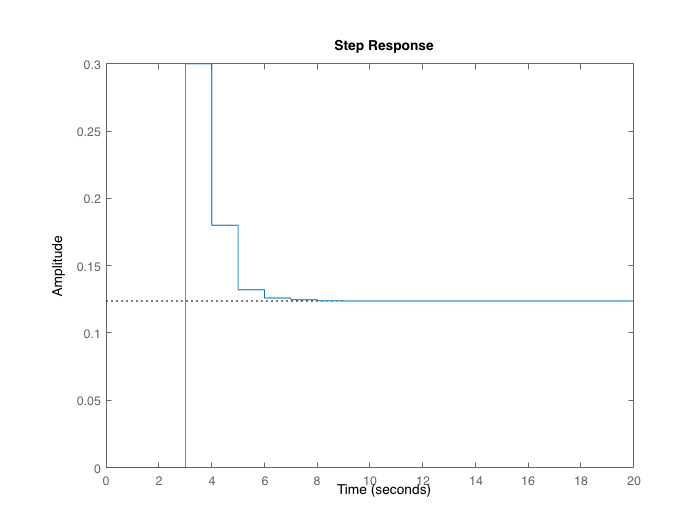

step(G)

m


%funcion de ponderacion respuesta a u=1
u=1;
arr = [0];
answ = [0];
sol = 0;
grad = 0;
for i = 0:5
        sol = sol + subs(g, n, i)
        answ(i+1) = sol;
end
plot(answ)

a =[0];
sol = 0;
for k = 0 :5
    for i = 0:k
        u=sin(k-i);
        grad = subs(g,n,i);
        arr(i+1) = grad*u;
        sol = sum(arr);
    end
    a(k+1)= sol
end
plot(a)